# Introducción a matemática simbólica

Matlab cuenta con un toolbox de matemática simbólica (ver [[1]](https://www.mathworks.com/products/symbolic.html) y [[2]](https://www.mathworks.com/help/symbolic/)), en este se pueden trabajar funciones simbólicas que representan funciones matemáticas. 

Dichas funciones se utilizan para diferenciar, integrar, resolución de ecuaciones diferenciales ordinarias y otras operaciones matemáticas.

## Creación de variables, parámetros y funciones simbólicas

syms a b c      %Definición de variables
b = sym(1/2)    %Definición de parámetros

$$b = \frac{1}{2}$$

syms f(x,y)                 %Definición inicial de funciones simbólicas
                            %junto a sus variables independientes

f(x,y) = x^2 + 7*x*y + y^2  %Especificación de la expresión matemática

$$f(x, y) = x^{2}+7\,x\,y+y^{2}$$

Evaluación de funciones simbólicas

x1 = 0:5;           %Vectores de valores de variable independiente x1=[0,1,2,3,4,5]
y1 = 1:2:11;        %Vectores de valores de variable independiente y1 = [1,3,5,7,9,11]
f(x1, y1)           %Evaluar los valores de las variables independientes

$$ans = \left(\begin{array}{cccccc} 1 & 31 & 99 & 205 & 349 & 531 \end{array}\right)$$

## Funciones básicas para el curso

### solve

Solución simbólica de ecuaciones algebraicas 

syms x
ecu = x^2 + 3*x +2 == 0

$$ecu = x^{2}+3\,x+2=0$$

sol = solve(ecu) 

$$sol = \left(\begin{array}{c} -2\\ -1 \end{array}\right)$$

**subs**

Substituye variables en expresiones simbólicas

syms x
eqn = sin(2*x) + cos(x) == 0

$$eqn = \sin\left(2\,x\right)+\cos\left(x\right)=0$$

[solx, params, conds] = solve(eqn, x, 'ReturnConditions', true)

$$solx = \left(\begin{array}{c} \frac{\pi }{2}+\pi \,k\\ 2\,\pi \,k-\frac{\pi }{6}\\ \frac{7\,\pi }{6}+2\,\pi \,k \end{array}\right)$$

$$params = k$$

$$conds = \left(\begin{array}{c} k\in \mathbb{Z}\\ k\in \mathbb{Z}\\ k\in \mathbb{Z} \end{array}\right)$$

subs(solx, k, 10)

$$ans = \left(\begin{array}{c} \frac{21\,\pi }{2}\\ \frac{119\,\pi }{6}\\ \frac{127\,\pi }{6} \end{array}\right)$$

### vpasolve

Solución numérica de ecuaciones algebraicas

syms x
ecu = x^3 + 3*x +2 == 0;
sol = vpasolve(ecu,x) 

$$sol = \left(\begin{array}{c} -0.59607163798332152311280541439968\\ 0.29803581899166076155640270719984+1.8073394944520218535764598429639\,\mathrm{i}\\ 0.29803581899166076155640270719984-1.8073394944520218535764598429639\,\mathrm{i} \end{array}\right)$$

### inv

Inversa de una matriz cuadrada 

syms a b c d
M = [a b; c d];
inv(M)

$$ans = \left(\begin{array}{cc} \frac{d}{a\,d-b\,c} & -\frac{b}{a\,d-b\,c}\\ -\frac{c}{a\,d-b\,c} & \frac{a}{a\,d-b\,c} \end{array}\right)$$

### simplify

Simplificación algebraica

syms x a b c
Identity = sin(x)^2 + cos(x)^2

$$Identity = {\cos\left(x\right)}^{2}+{\sin\left(x\right)}^{2}$$

S = simplify(Identity)

$$S = 1$$

### expand

Expande expresiones y simplifica las entradas de funciones mediante el uso de identidades

syms x
p = (x - 2)*(x - 4)

$$p = \left(x-2\right)\,\left(x-4\right)$$

expand(p)

$$ans = x^{2}-6\,x+8$$

### symunit

Agrega unidades de medida a las variables y parámetros simbólicos

u = symunit;
length = 3*u.m       %unidades de distancia (metros)

$$length = 3\,m$$

g = 9.81*u.m/u.s^2   %unidades para aceleración (metros/segundo^2)

$$g = \frac{981}{100}\,\frac{m}{s^{2}}$$

### unitConvert

Sirve para hacer conversiones de unidades

m = 2*u.kg;             %masa
a = 5*u.m/u.s^2;        %aceleración
F = m*a                 %Fuerza

$$F = 10\,\frac{\mathrm{kg}\,m}{s^{2}}$$

F = unitConvert(F,u.N)  %unidades en Newton

$$F = 10\,N$$

### rewrite

Reescribir una expresión en términos de otra función

syms x
rewrite(cos(x),'sin')

$$ans = 1-2\,{\sin\left(\frac{x}{2}\right)}^{2}$$

### coeffs

Coeficientes de un polinomio

syms x
Poly = 16*x^2 + 19*x + 11;
c = coeffs(Poly)

$$c = \left(\begin{array}{ccc} 11 & 19 & 16 \end{array}\right)$$

### fplot

Se logran graficar expresiones o funciones simbólicas

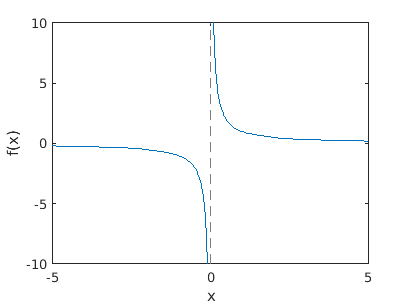

syms x
f = 1/x;
fplot(f)
xlabel('x')
ylabel('f(x)')

### limit

Calcula el límite de una función

syms x
f = 1/x;
limit(f,x,0)            %límite bidireccional

$$ans = \mathrm{NaN}$$

limit(f,x,0,'right')    %límite por la derecha

$$ans = \infty$$

limit(f,x,0,'left')     %límite por la izquierda

$$ans = -\infty$$

### diff

Diferencia una expresión o función simbólica

syms x 
f = x^3

$$f = x^{3}$$

diff(f)

$$ans = 3\,x^{2}$$

### int

Realiza integrales definidas e indefinidas

syms x

expr = 1+x^2;
F = int(x)      %Integral indefinida de una función univariada

$$F = \frac{x^{2}}{2}$$

syms x z
f(x,z) = x/(1+z^2);
Fx = int(f,x)   %Integral indefinida de una función multivariada en terminos de x

$$Fx(x, z) = \frac{x^{2}}{2\,\left(z^{2}+1\right)}$$

syms x
expr = 1-exp(-x);
F = int(expr,[0 1])   %Integral definida entre 0 y 1           

$$F = {\mathrm{e}}^{-1}$$

### taylor

Obtiene series de taylor de una expresión

syms x
f = exp(x);
T1 = taylor(f)

$$T1 = \frac{x^{5}}{120}+\frac{x^{4}}{24}+\frac{x^{3}}{6}+\frac{x^{2}}{2}+x+1$$

## **Otros ejemplos**